% execute math script
out = evalc('hobbing');
clearvars out ans

## Bedatung der Variablen für die Simulation

### Werkstück offset

a = 0;
b = 0;
c = 0;
% point of interest
poi = [-60 0 11.4937];      % [mm] punkt in werkzeugkoordinaten

### Vorschübe

#### x-Achse

fX_WZrad = 0;
x = 300;    % [mm] abstand in CSYS zu WZ-CS

#### z-Achse

fZ_WZrad = 0;
z = 75;     % [mm] abstand in CSYS zu WZ-CS

#### y-Achse

fY_WZrad = 0;
y = 0;
Y_shift = 0;

#### C-Achse

zWst = 50;              % zähnezahl werkstuck
zWz = 1;                % zähnezahl werkzeug
f_WSTrad = zWz / zWst;
ga = 0;                 % werkstuckwinkel offset

#### A-Achse

A = 0;          % winkel A in rad

## Berechnung

### analytische Berechnung

die analytische berechnung muss vor dem simulink model erfolgen, dieses benötigt die ausgabe in traj

nSchritt = 1e2;
% drehgechwindigkeit
slopeB = nB;

anaT = linspace(0,tSim,nSchritt+1)';
currB = 0;
traj = nan(length(anaT),3);
logB = nan(length(anaT),1);

iterT = tic;
% 1:nSchritt+1
for schritt = 1:length(anaT)
    currB = slopeB * anaT(schritt);
    B = currB;
    logB(schritt) = B;
    TMgesamt = double(vpa(subs(Gesamt)));
    traj(schritt,:) = applytm(poi',TMgesamt)';
    %     traj(schritt,:) = app
end
fprintf('[ %s ] time to run the iteration: %.3f sec.\n',datestr(now,'HH:mm:ss'),toc(iterT))

[ 13:10:22 ] time to run the iteration: 9.377 sec.


### Simulation

nB = 1;         % 1*s^-1, drehzahl der b-achse

% simulation setup
tSim = 32*pi;
simOut = sim('ASM00021');

Daten extrahieren

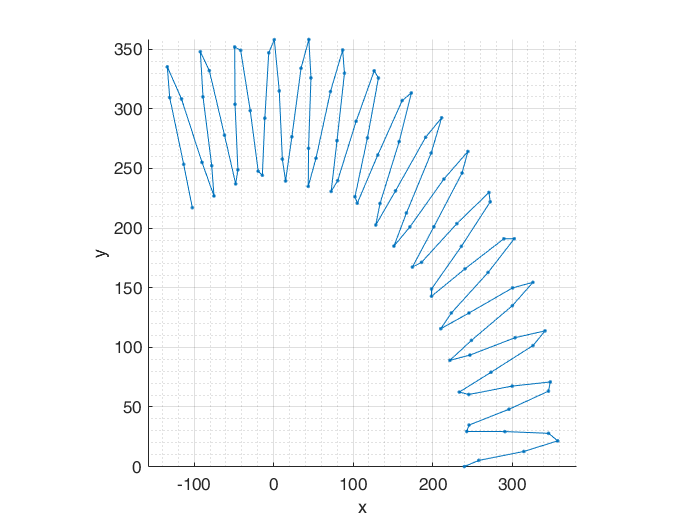

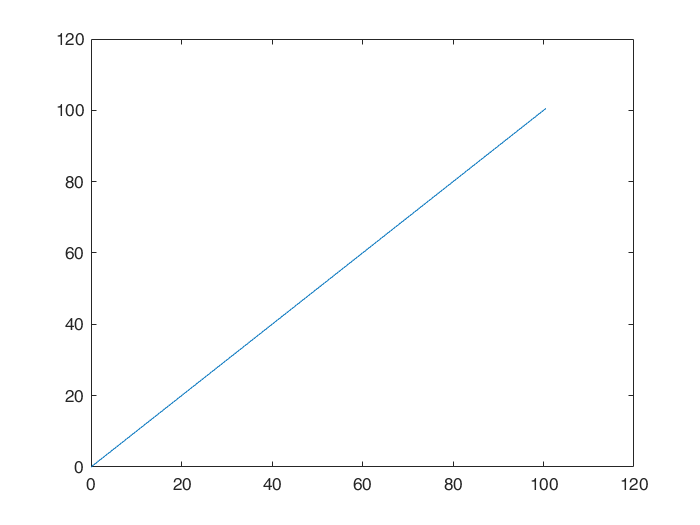

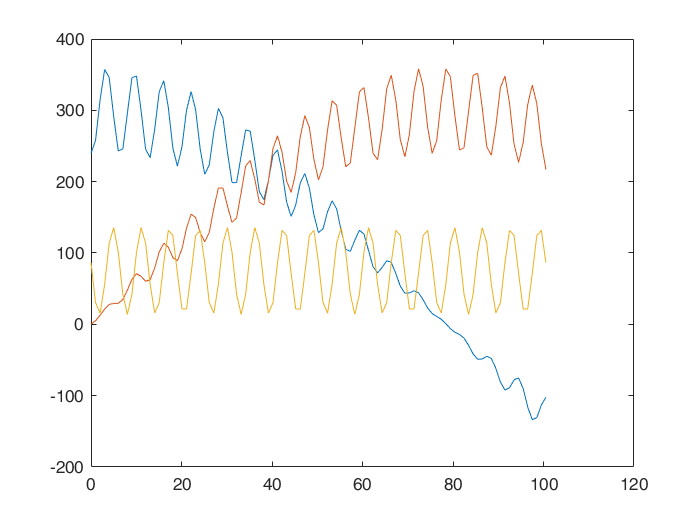

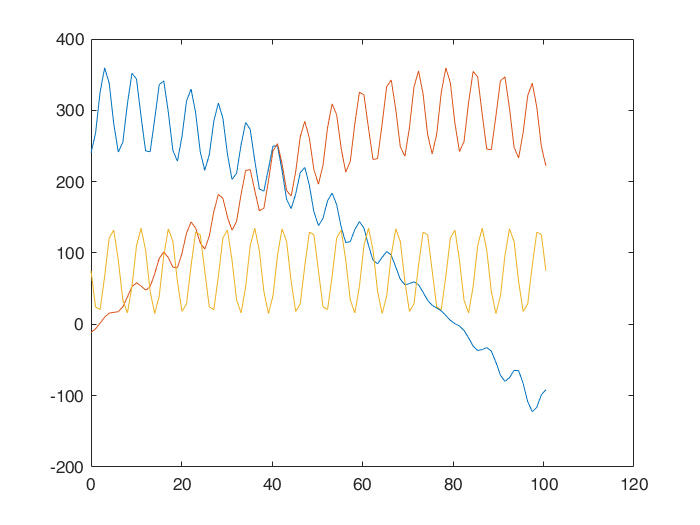

simT = simOut.logsout{1}.Values.Time;
simCord = simOut.logsout{1}.Values.Data; % [m]
simCord = simCord * 1e3; % [mm]
simCordRS = interp1(simT,simCord,anaT);